# 1.2.15. Аппроксимация данных

**Практическое занятие**

Необходимо аппроксимировать температурные данные, чтобы восстановить пропуски и прогнозировать температуру на будущее.

## Чтение данных

1. Считайте данные из файла `temp05.xlsx` в переменную `T` типа `table` (подсказка: `readrable()`)

T = 1808×4 table
       DATE       TAVG     TMAX     TMIN 
    __________    _____    _____    _____

    01.01.2010     -9.6     -5.3    -14.6
    02.01.2010    -13.2    -11.4    -16.3
    03.01.2010    -17.2    -14.1    -19.4
    04.01.2010      -18    -14.5    -21.3
    05.01.2010    -11.9    -10.4    -14.8
    06.01.2010    -13.7    -11.5    -15.5
    07.01.2010    -12.4     -9.6    -15.8
    08.01.2010     -7.2     -4.8     -9.6
    09.01.2010     -8.9     -4.8    -15.2
    10.01.2010    -17.3      -14    -20.8
    11.01.2010    -15.2     -9.6    -18.8
    12.01.2010    -14.3     -9.9    -17.7
    13.01.2010    -10.2     -7.3    -15.1
    14.01.2010     -8.8     -7.5    -10.7
    15.01.2010     -9.6       -7    -12.2
    16.01.2010       -9     -7.8    -13.5


2. Визуализируйте данные: постройте график столбца `TMAX` от столбца `DATE` (подсказка: `plot()`)

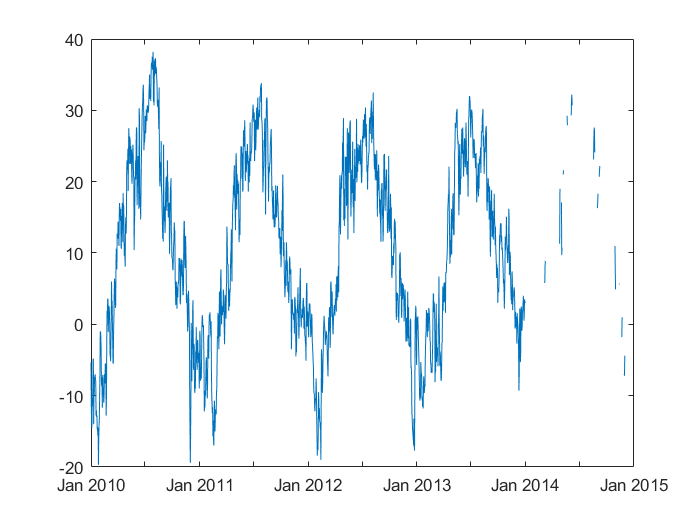

На графике видны пропущенные занчения, которые мешают работать с сигналом, и которые нужно восстановить. Но встроенная функция `fillmissing` здесь не подойдет, потому что она не учитывает низкочастотный характер сигнала. Чтобы восстановить пропущенные данные, нужно аппроксимировать данные математическим законом: в данном случае подойдет гармонический.

## Подготовка данных

Прежде чем приступить к работе с данными, необходимо перевести столбец времени (`DATE`) в тип `double`, потому что с `datetime` алгоритмы аппроксимации не работают.

Создайте переменную `dur`, в которую запишите разницу между каждым моментом времени (`DATE`) и началом измерения (первый элемент `DATE`). Должен получиться монотонно возрастающий вектор типа `duration` (подсказка: `-`, `(1)`)

Переведите вектор `dur` в года и результат запишите в столбец `YEAR` таблицы `T`. Новый столбец будет иметь тип `double` (подсказка: `years()`). 

T = 1808×5 table
       DATE       TAVG     TMAX     TMIN       YEAR   
    __________    _____    _____    _____    _________

    01.01.2010     -9.6     -5.3    -14.6            0
    02.01.2010    -13.2    -11.4    -16.3    0.0027379
    03.01.2010    -17.2    -14.1    -19.4    0.0054758
    04.01.2010      -18    -14.5    -21.3    0.0082137
    05.01.2010    -11.9    -10.4    -14.8     0.010952
    06.01.2010    -13.7    -11.5    -15.5      0.01369
    07.01.2010    -12.4     -9.6    -15.8     0.016427
    08.01.2010     -7.2     -4.8     -9.6     0.019165
    09.01.2010     -8.9     -4.8    -15.2     0.021903
    10.01.2010    -17.3      -14    -20.8     0.024641
    11.01.2010    -15.2     -9.6    -18.8     0.027379
    12.01.2010    -14.3     -9.9    -17.7     0.030117
    13.01.2010    -10.2     -7.3    -15.1 

Далее будем использовать функции из пакета [Curve Fitting Toolbox](https://www.mathworks.com/products/curvefitting.html) - профессионального инструмента аппроксимации.

Как вы убедились, столбец `TMAX` содержит пропущенные значения и не может быть напрямую использован для аппроксимации. Подготовьте данные для аппроксимации с помощью функции `prepareCurveData()`. Передайте ей столбцы `YEAR` и `TMAX`, результат запишите в переменные `x`, `y` (подсказка: `[...,...] = prepareCurveData(...,...)`)

x =          0
    0.0027
    0.0055
    0.0082
    0.0110
    0.0137
    0.0164
    0.0192
    0.0219
    0.0246


y =    -5.3000
  -11.4000
  -14.1000
  -14.5000
  -10.4000
  -11.5000
   -9.6000
   -4.8000
   -4.8000
  -14.0000


Функция `prepareCurveData()` удаляет пропуски, приводит данные к численному типу и выполняет некоторые другие операции, чтоы подготовить данные для аппроксимации. Полный список выполняемых действий посмотрите в документации к функции:

Чтобы аппроксимация сработала лучше данные желательно нормировать. В данном случае достаточно привести среднее значение к нулю.

Среднее значение вектора `y` запишите в переменную `TM`, чтобы его сохранить (подсказка: `mean()`)

TM = 10.5069

Вычтите из вектора `y` его среднее значение. Результат запишите в `y`

y =   -15.8069
  -21.9069
  -24.6069
  -25.0069
  -20.9069
  -22.0069
  -20.1069
  -15.3069
  -15.3069
  -24.5069


Взуализируйте исходные данные для апроксимации: постройте график `y` от `x` (подсказка: `plot()`)

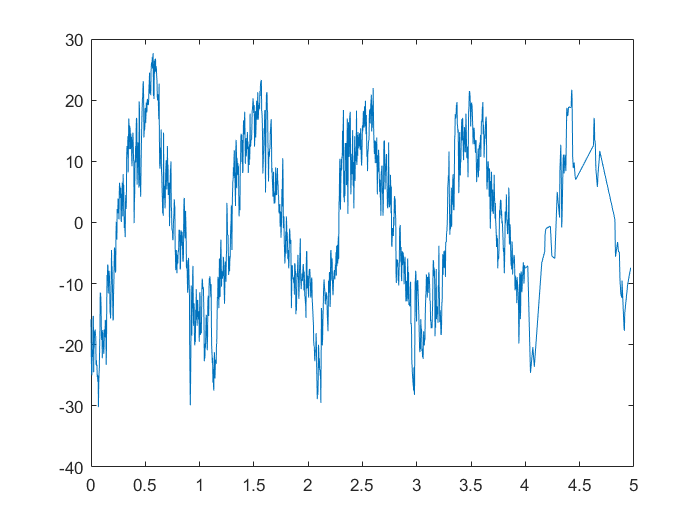

Из графика видно, что пропуски отсутствуют, среднее значение равно нулю, по оси обсцисс вместо временных меток отложено количество лет, прошедшее с начала измерения (с 01.01.2010). Такие данные можно использовать для аппроксимации.

## Аппроксимация данных

Из последнего графика видно, что сигнал можно аппроксимировать синусоидой, которая будет отражать сезонные колебания температуры.

Найдите аппроксимационную модель сигнала y(x) с помощью функции `fit()`, передав ей в качестве желаемой модели `'sin1'` третьим аргументом. Модель запишите в переменную `f` (подсказка: `fit(...,...,'sin1')`)

f =      General model Sin1:
     f(x) =  a1*sin(b1*x+c1)
     Coefficients (with 95% confidence bounds):
       a1 =       16.84  (16.48, 17.19)
       b1 =       6.285  (6.268, 6.302)
       c1 =      -1.777  (-1.819, -1.736)

Изучите переменную `f`. Она модержит значения переметров синусоиды с доверительным интервалами. Таким образом, суточные колебания температуры можно описать четырьмя параметрами: `a1` - маплитуда колебаний, `b1` - частота, `c1` - сдвиг по фазе, `TM` - смещение температуры.

Примечание: для построения аппроксимационных моделей также можно использовать графический инструмент *Curve Fitting Tool*

Визуально проверьте качество аппроксимации: на одном графике постройте полученную модель и исходные данные y(x) (подсказка: `doc('plot cfit')`)

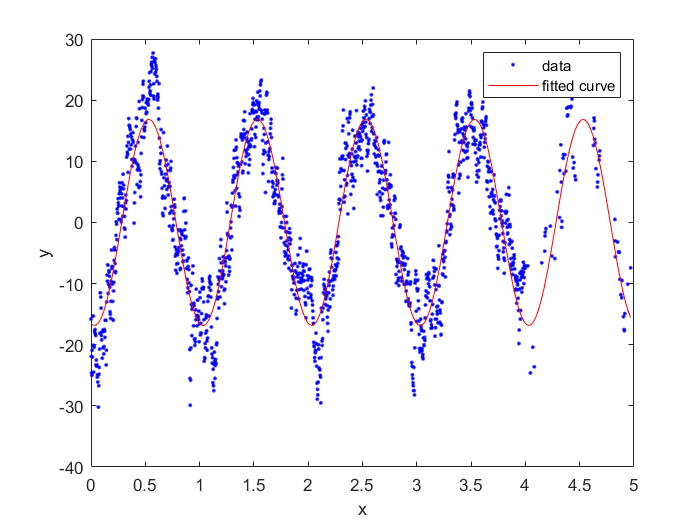

Если модель выглядит субъективно адекватно исходным данным, значит, её можно использовать для восстановления попущенных значений, а также для прогнозирования температуры на любой день за пределами исходной выборки.

## Восстановление пропусков

Столбец `YEAR` таблицы `T`, в отличие от полученной из него переменной `x`, имеет временные метки даже для тех точек, которые пропущены, и которые мы хотим восстановить. Используйте его для получения нового столбца `TMAX1`, которые содержит аппроксимированные значения, полученные из модели `f` (подсказка: `f(...)`)

T = 1808×6 table
       DATE       TAVG     TMAX     TMIN       YEAR        TMAX1 
    __________    _____    _____    _____    _________    _______

    01.01.2010     -9.6     -5.3    -14.6            0    -16.479
    02.01.2010    -13.2    -11.4    -16.3    0.0027379    -16.536
    03.01.2010    -17.2    -14.1    -19.4    0.0054758    -16.588
    04.01.2010      -18    -14.5    -21.3    0.0082137    -16.635
    05.01.2010    -11.9    -10.4    -14.8     0.010952    -16.677
    06.01.2010    -13.7    -11.5    -15.5      0.01369    -16.715
    07.01.2010    -12.4     -9.6    -15.8     0.016427    -16.747
    08.01.2010     -7.2     -4.8     -9.6     0.019165    -16.775
    09.01.2010     -8.9     -4.8    -15.2     0.021903    -16.797
    10.01.2010    -17.3      -14    -20.8     0.0246

И не забудьте, что среднее значение температуры, хранящееся в `TM`, нужно восстановить. Сместите значения столбца `TMAX1` на величину `TM`

T = 1808×6 table
       DATE       TAVG     TMAX     TMIN       YEAR        TMAX1 
    __________    _____    _____    _____    _________    _______

    01.01.2010     -9.6     -5.3    -14.6            0    -5.9719
    02.01.2010    -13.2    -11.4    -16.3    0.0027379    -6.0289
    03.01.2010    -17.2    -14.1    -19.4    0.0054758     -6.081
    04.01.2010      -18    -14.5    -21.3    0.0082137    -6.1283
    05.01.2010    -11.9    -10.4    -14.8     0.010952    -6.1705
    06.01.2010    -13.7    -11.5    -15.5      0.01369    -6.2079
    07.01.2010    -12.4     -9.6    -15.8     0.016427    -6.2403
    08.01.2010     -7.2     -4.8     -9.6     0.019165    -6.2677
    09.01.2010     -8.9     -4.8    -15.2     0.021903    -6.2902
    10.01.2010    -17.3      -14    -20.8     0.0246

Найдите логические индексы пропущенных элементов столбца `TMAX` (подсказка: `ismissing()`). Запишите их в переменную `i`

i = 1808×1 logical array
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


Используя логические индексы `i`, замените в столбце `TMAX` пропущенные значения на соответствующие значения из столбца `TMAX1`

T = 1808×6 table
       DATE       TAVG     TMAX     TMIN       YEAR        TMAX1 
    __________    _____    _____    _____    _________    _______

    01.01.2010     -9.6     -5.3    -14.6            0    -5.9719
    02.01.2010    -13.2    -11.4    -16.3    0.0027379    -6.0289
    03.01.2010    -17.2    -14.1    -19.4    0.0054758     -6.081
    04.01.2010      -18    -14.5    -21.3    0.0082137    -6.1283
    05.01.2010    -11.9    -10.4    -14.8     0.010952    -6.1705
    06.01.2010    -13.7    -11.5    -15.5      0.01369    -6.2079
    07.01.2010    -12.4     -9.6    -15.8     0.016427    -6.2403
    08.01.2010     -7.2     -4.8     -9.6     0.019165    -6.2677
    09.01.2010     -8.9     -4.8    -15.2     0.021903    -6.2902
    10.01.2010    -17.3      -14    -20.8     0.0246

Визуализируйте восстановленный сигнал `TMAX` от даты `DATE` (подсказка: `plot()`)

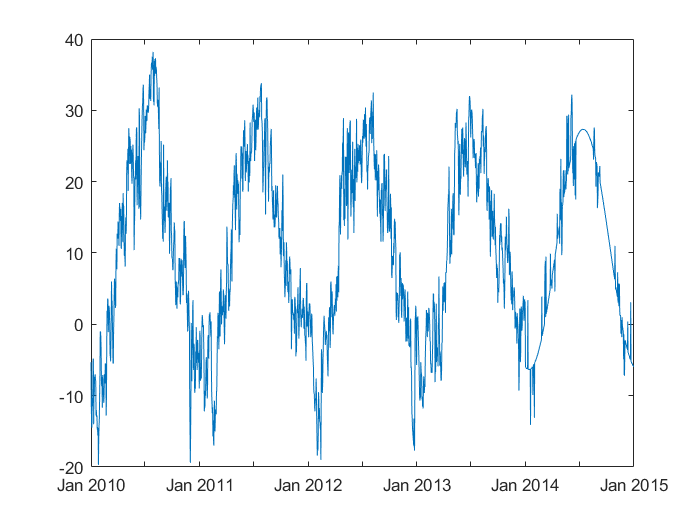

Из графика видно, как пропуски заменились кусками синусоиды.

При желании значения `TMAX1` можно использовать в качестве температурных данных, очищенных от шумов, а аппроксимацию рассматривать как метод сглаживания данных.

## Прогнозирование

Исходные данные содержат температуру за 5 лет. Используя полученную аппроксимационную модель (`f`, `TM`), спрогнозируйте температуру еще на 5 лет вперед (до 2020 года).

Для этого сначала нужно создать соответствующий вектор дат. Начните с создания переменной `d1` типа `datetime`, которая хранит метку `01.01.2010` (подсказка: `datetime()`)

d1 = datetime
   01-Jan-2010


Затем создайте переменную `d2`, которая хранит дату `31.12.2019`

d2 = datetime
   31-Dec-2019


Теперь создайте вектор `D`, который хранит равномерно распределенные значения с интервалом в один день между `d1` и `d2` (подсказка: `:`)

D = 1×3652 datetime array
Columns 1 through 714

   01-Jan-2010   02-Jan-2010   03-Jan-2010   04-Jan-2010   05-Jan-2010   06-Jan-2010   07-Jan-2010   08-Jan-2010   09-Jan-2010   10-Jan-2010   11-Jan-2010   12-Jan-2010   13-Jan-2010   14-Jan-2010   15-Jan-2010   16-Jan-2010   17-Jan-2010   18-Jan-2010   19-Jan-2010   20-Jan-2010   21-Jan-2010   22-Jan-2010   23-Jan-2010   24-Jan-2010   25-Jan-2010   26-Jan-2010   27-Jan-2010   28-Jan-2010   29-Jan-2010   30-Jan-2010   31-Jan-2010   01-Feb-2010   02-Feb-2010   03-Feb-2010   04-Feb-2010   05-Feb-2010   06-Feb-2010   07-Feb-2010   08-Feb-2010   09-Feb-2010   10-Feb-2010   11-Feb-2010   12-Feb-2010   13-Feb-2010   14-Feb-2010   15-Feb-2010   16-Feb-2010   17-Feb-2010   18-Feb-2010   19-Feb-2010   20-Feb-2010   21-Feb-2010   22-Feb-2010   23-Feb-2010   24-Feb-2010   25-Feb-2010   26-Feb-2010   27-Feb-2010   28-Feb-2010   01-Mar-2010   02-Mar-2010   03-Mar-2010   04-Mar-2010   05-Mar-2010   06-Mar-2010   07-Mar-2010   08-Mar-2010   09-Mar-201

Как вы помните, аппроксимационная модель `f` работает с вектором лет типа `double`.

Поэтому сначала в переменную `dur` запишите временные интервалы между первой датой `Y` и всеми остальными

`Затем в Y` запишите вектор лет от `dur` (подсказка: `years()`)

Y =          0    0.0027    0.0055    0.0082    0.0110    0.0137    0.0164    0.0192    0.0219    0.0246    0.0274    0.0301    0.0329    0.0356    0.0383    0.0411    0.0438    0.0465    0.0493    0.0520    0.0548    0.0575    0.0602    0.0630    0.0657    0.0684    0.0712    0.0739    0.0767    0.0794    0.0821    0.0849    0.0876    0.0904    0.0931    0.0958    0.0986    0.1013    0.1040    0.1068    0.1095    0.1123    0.1150    0.1177    0.1205    0.1232    0.1259    0.1287    0.1314    0.1342


Используйте модель `f` и вектор `Y` для предказания температуры. Результат запишите в переменную `P` (подсказка: `f(...)`)

P =   -16.4788
  -16.5358
  -16.5880
  -16.6352
  -16.6775
  -16.7148
  -16.7472
  -16.7747
  -16.7971
  -16.8146


На забудьте восстановить для P среднее значение TM

На одном графике постройте исходные данные TMAX(DATE) и предсказанные P(D) (подсказка: `plot(...,...,...,...)`)

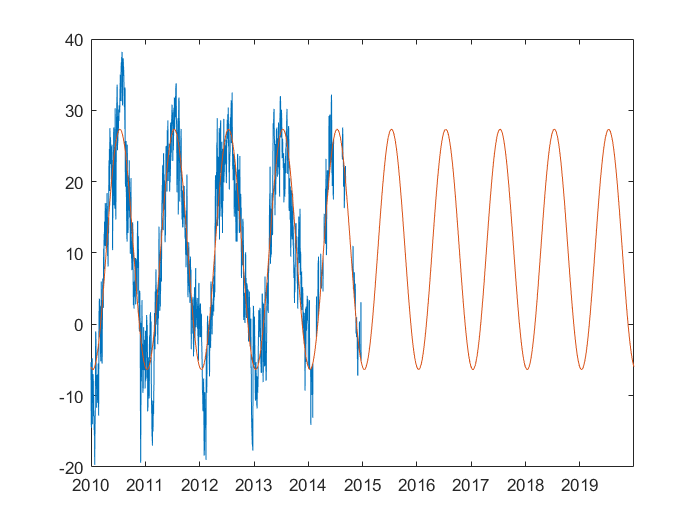

Вы просчитали изменение максимальной суточной температуры на 5 лет вперед. Обратите внимание, что ваша прогнозирующая модель не учитывает глобальное потепление (постоянное небольшое нарастание температуры от года к году), которое можно было бы промоделировать линейным трендом. Поэтому эта полученная модель заведомо будет давать погрешность при предсказании на десятки лет вперед.

Чтобы учесть эффект глобального потепления, понадобится более сложная аппроксимационная модель (учитывающая еще и тренд) и более широкий набор данных, на котором этот эффект может быть достоверно выявлен.